addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\functions')
addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\data')
addpath('D:\matlabfiles\CourseMaterial\CourseMaterial\Code\yxx\')
clear; clc;
close all;
load projectData24.mat
k       = 3;                                            % Prediction horizon.
groupNo = 49;                                            % Example group number.
nolags  = 200;
sweek   = 168;
sday    = 24;                                           % Daily season.

## Set appropriate path.

Your exam code should all be stored in a subfolder with the name "group001" (if you are group one). Any functions you use should be stored in this folder. The common code from the course book is stored in the folder "functions" in the same directory as your folder (you do not need to include these in your folder). 

grpStr = num2str( groupNo );
switch length(grpStr)
    case 1       
        grpStr = append("00", grpStr); 
    case 2       
        grpStr = append("0", grpStr); 
end
grpStr = append("group", grpStr);
addpath('../functions', '../data', grpStr)              % Sets the path to your code.

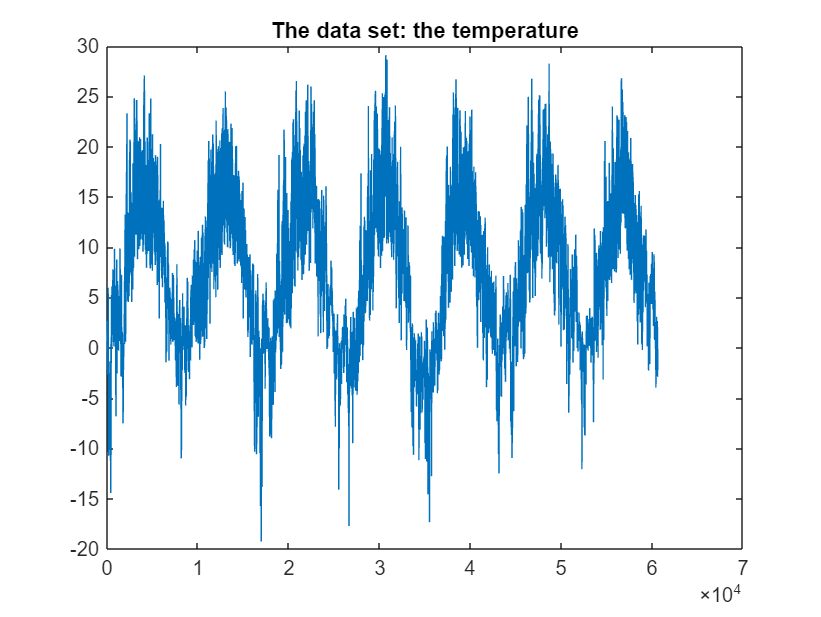



% Show entire data set, transform, and select training data.
figure 
plot(data(:,8)),          
title('The data set: the temperature');

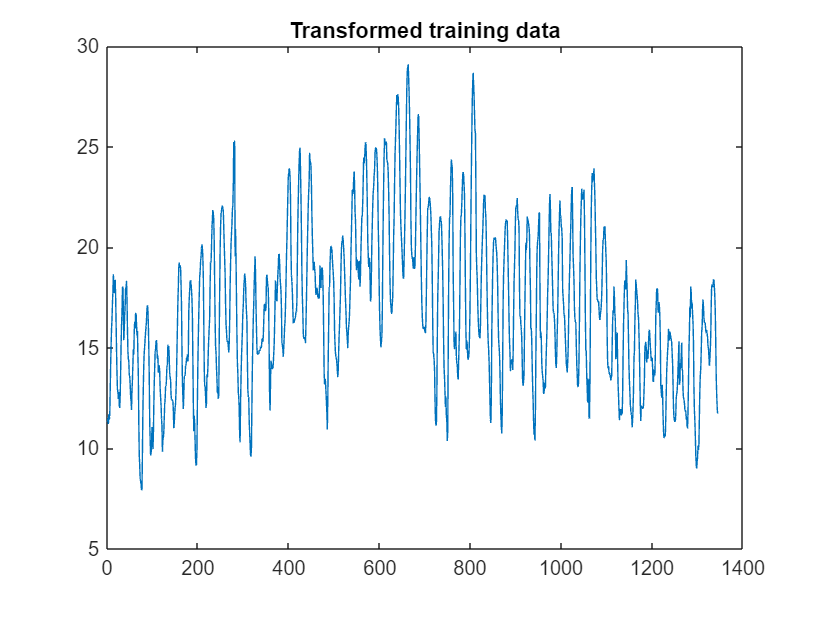


DataInd=data(:,8);
Data=DataInd(1:50000);
DataTestInd=50001:60624;
DataTest=DataInd(50001:end);                          % Leave some data to test the predictor


trainDataInd = 30025:30024+sweek*8;                     % Select some training data; these 8 weeks seems nice.
trainingData = Data(trainDataInd);                      % Notice that the model is build on only the training data.


figure, plot(trainingData),		
title('Transformed training data');

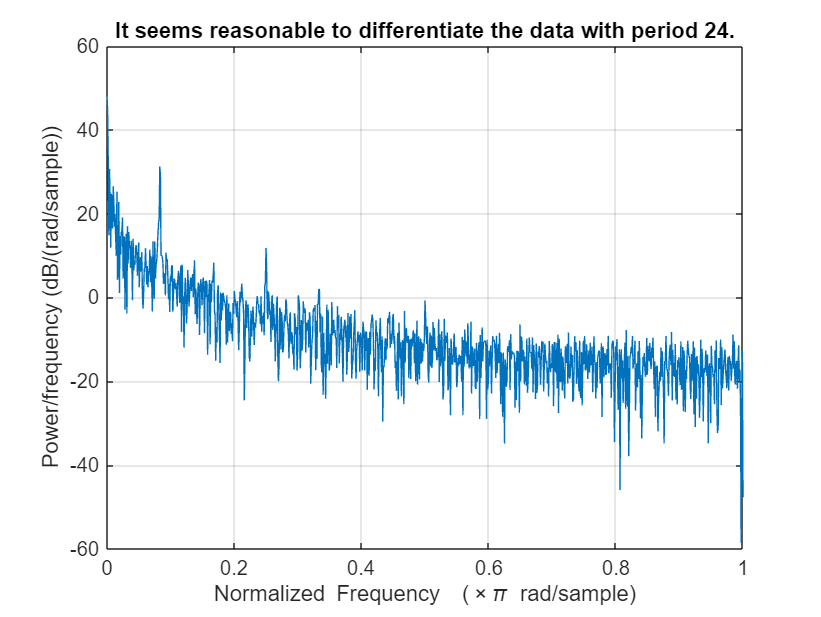

% Part A: ARMA Model
figure 
periodogram(trainingData);                    % Seems reasonable to differentiate the data with period 24.
title('It seems reasonable to differentiate the data with period 24.')

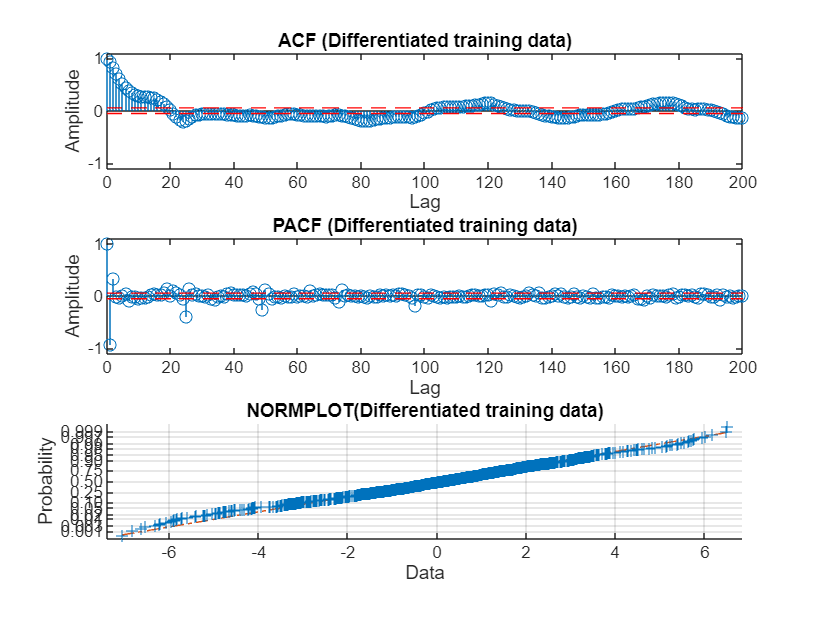

A24=[1 zeros(1,23) -1];
data = filter(A24,[1],trainingData);          
data = data(25:end);                          %throw away the initial 24 values.
mdy=iddata(data);
acfs(data,nolags,'Differentiated training data');

% Seems a1 and a2 can be the first parameters.
model_init=idpoly([1 0 0],[],[]);
model_max=pem(mdy,model_init);
present(model_max)

model_max =
Discrete-time AR model: A(z)y(t) = e(t)                          
  A(z) = 1 - 1.254 (+/- 0.02588) z^-1 + 0.3454 (+/- 0.02591) z^-2
                                                                 
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Termination condition: Near (local) minimum, (norm(g) < tol)..
Number of iterations: 2, Number of function evaluations: 5    
                                                              
Estimated using PEM on time domain data "mdy".                
Fit to estimation data: 65.87% (prediction focus)             
FPE: 0.6114, MSE: 0.6095                                      
More information in model's "Report" property.
 


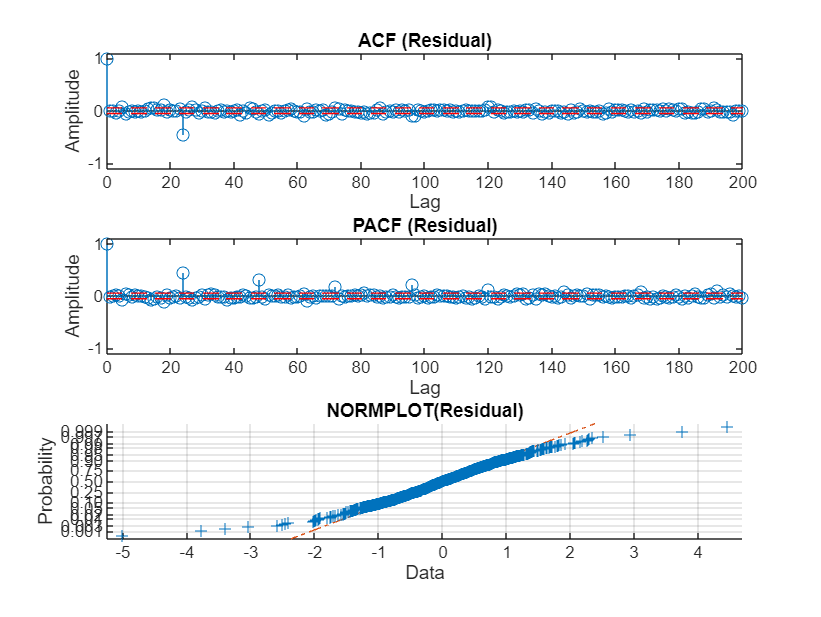

% All the parameters are significant. We can move on to residuals.
res=resid(model_max,mdy);
res=res(3:end);
acfs(res.y,nolags,'Residual');

% Time to look at ACF, 24 is obvious. Add c24 to the model.
model_init=idpoly([1 0 0],[],[1 zeros(1,24)]);
model_init.Structure.c.Free=[0 zeros(1,23) 1];
model_max=pem(mdy,model_init);
present(model_max)

model_max =
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                    
  A(z) = 1 - 1.282 (+/- 0.02642) z^-1 + 0.3255 (+/- 0.02641) z^-2
                                                                 
  C(z) = 1 - 0.8562 (+/- 0.01479) z^-24                          
                                                                 
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nc=24
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                       
Termination condition: Near (local) minimum, (norm(g) < tol)..
Number of iterations: 5, Number of function evaluations: 11   
                                                              
Estimated using PEM on time domain data "mdy".                
Fit to estimation data: 73.57% (prediction focus)             
FPE: 0.3674, MSE: 0.3658                                      
More information in mo

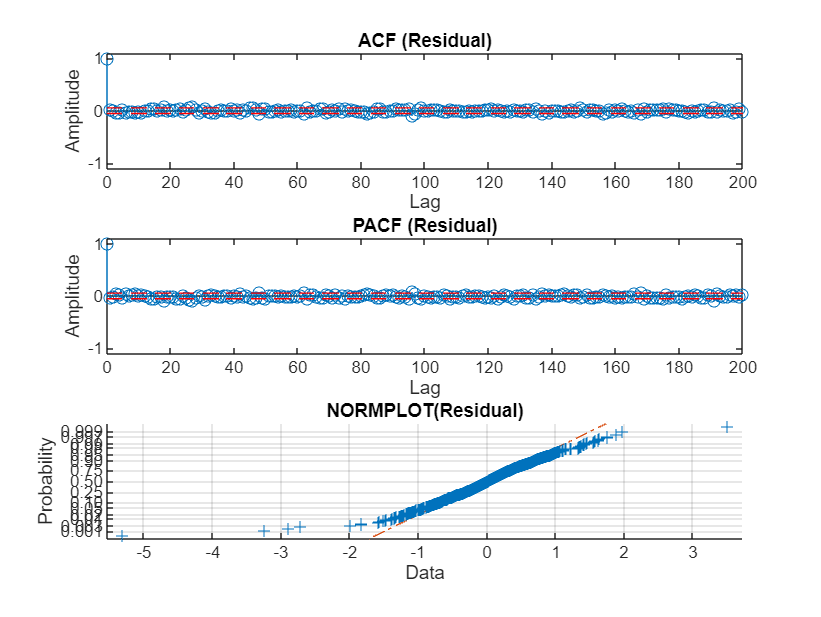

% All the parameters are significant. We can move on to residuals.
res=resid(model_max,mdy);
res=res(3:end);
acfs(res.y,nolags,'Residual');

% Seems white and normal, check it.
checkIfWhite(res.y)

The residual is deemed to be WHITE according to the Monti-test (as 26.75 < 31.41).


ans = logical
   1


The D'Agostino-Pearson's K2 test indicates that the Agostino-Pearson is NOT normal distributed.


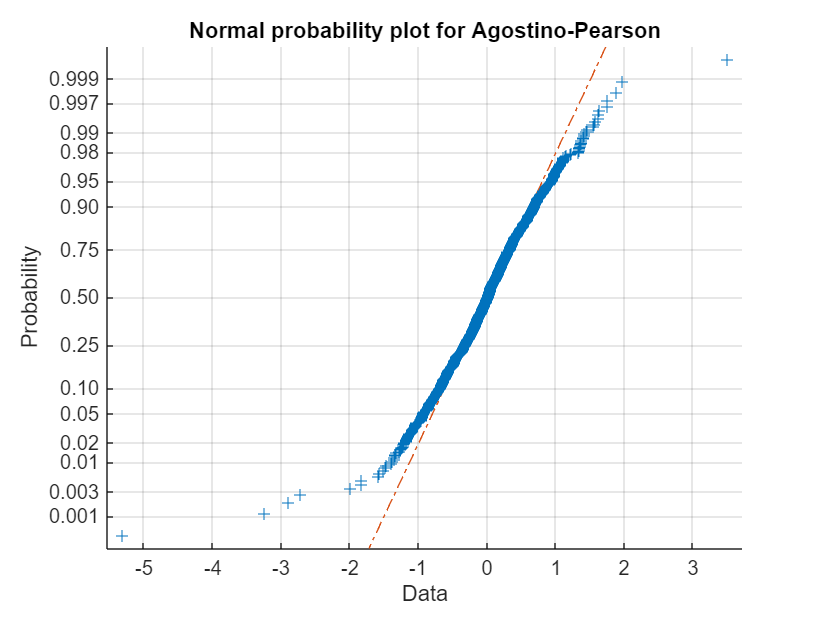

ans = logical
   0


checkIfNormal(res.y,'Agostino-Pearson')

% Not normal but seems Ok, leave it here, for now.

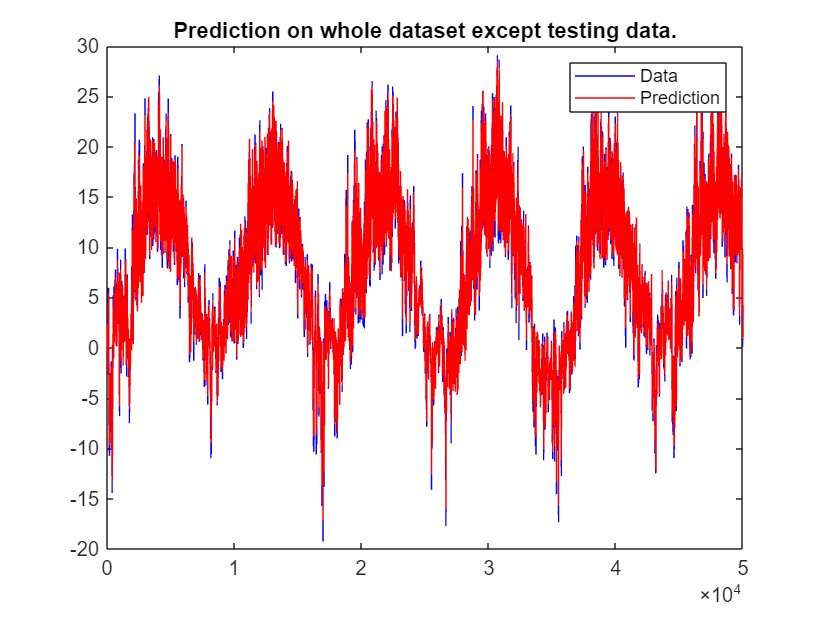

% Now we would like to do the prediction on the whole data set we
% have(except the test data). And then we can extract any part to be the
% validation data.
A=conv(model_max.A,[1 zeros(1,23) -1]);
[Fk,Gk]=polydivision(model_max.C,A,k);
yhat=filter(Gk,model_max.C,Data);
figure
subplot(1,1,1)
plot(1:50000,Data,'b');
hold on
plot(1:50000,yhat,'r');
hold off
title('Prediction on whole dataset except testing data.')
legend('Data','Prediction')

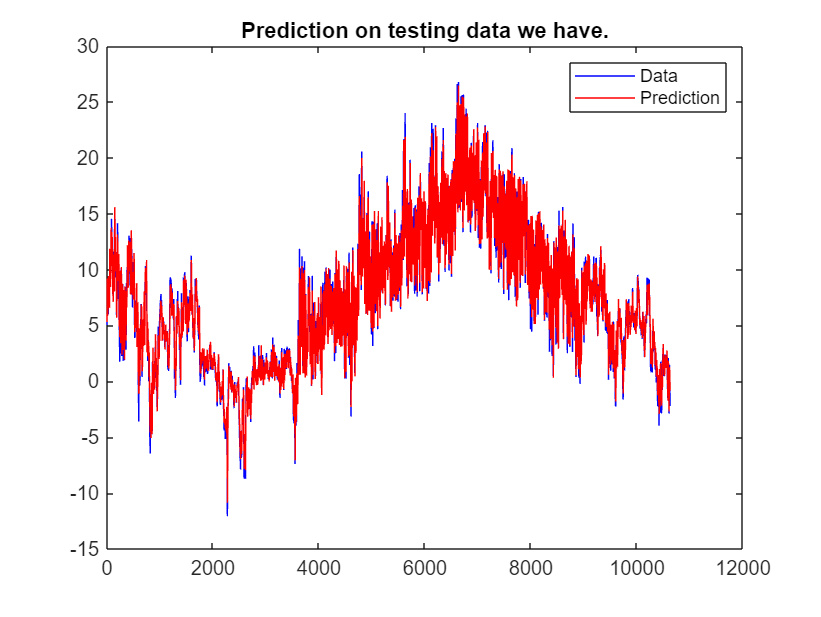

% Seems nice, we can do prediction on our testing data and see how good
% this predictor goes.
yhatpre=filter(Gk,model_max.C,DataInd);
yhatpre=yhatpre(50001:end);
figure
subplot(1,1,1)
plot(1:length(DataTest),DataTest,'b');
hold on
plot(1:length(DataTest),yhatpre,'r');
hold off
title('Prediction on testing data we have.')
legend('Data','Prediction')

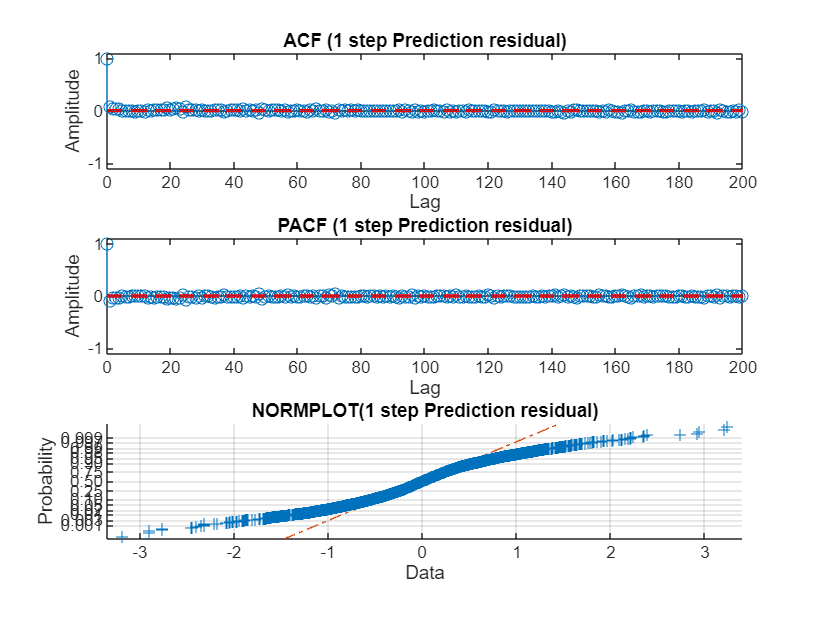

yhat1=predCodeA_grp049([],DataInd,DataTestInd,1);
ehatA_P1 = DataTest-yhat1;
var_predA_1a = var( ehatA_P1 );

ynaive=filter([zeros(1,1) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '1 step Prediction residual');

varY = var( DataTest );
fprintf('Prediction results for the 3-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    0.24. The normalized variance is 0.0063.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )
checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 163.16 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


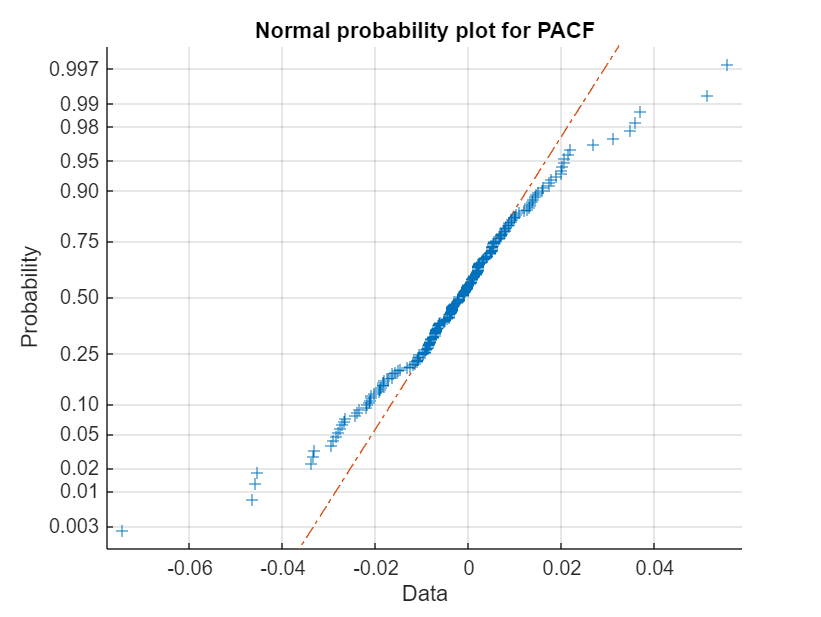

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

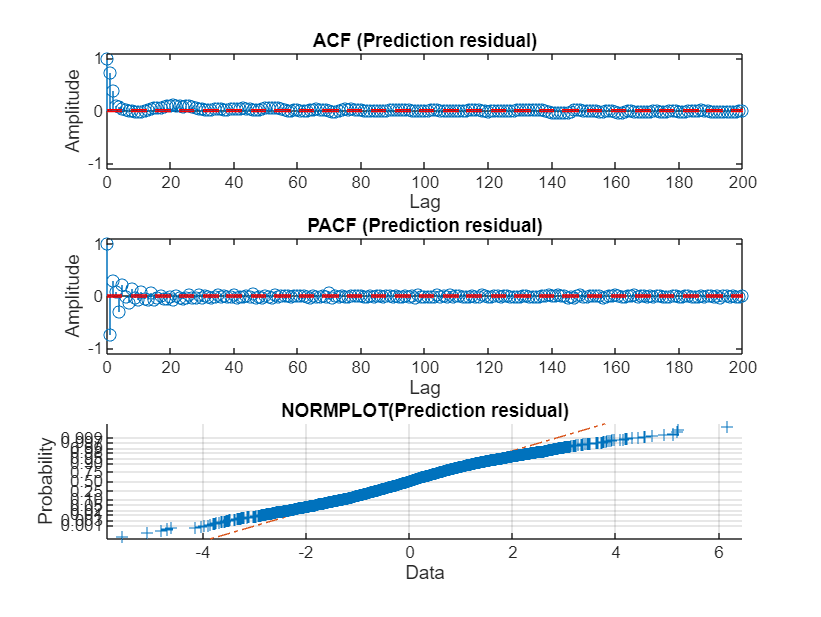


ehatA_P1 = DataTest-yhatpre;
var_predA_1a = var( ehatA_P1 );
[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '3 step Prediction residual');


ynaive=filter([zeros(1,3) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

varY = var( DataTest );
fprintf('Prediction results for the 3-step prediction:\n')

Prediction results for the k-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    1.19. The normalized variance is 0.0316.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )
checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 8854.03 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


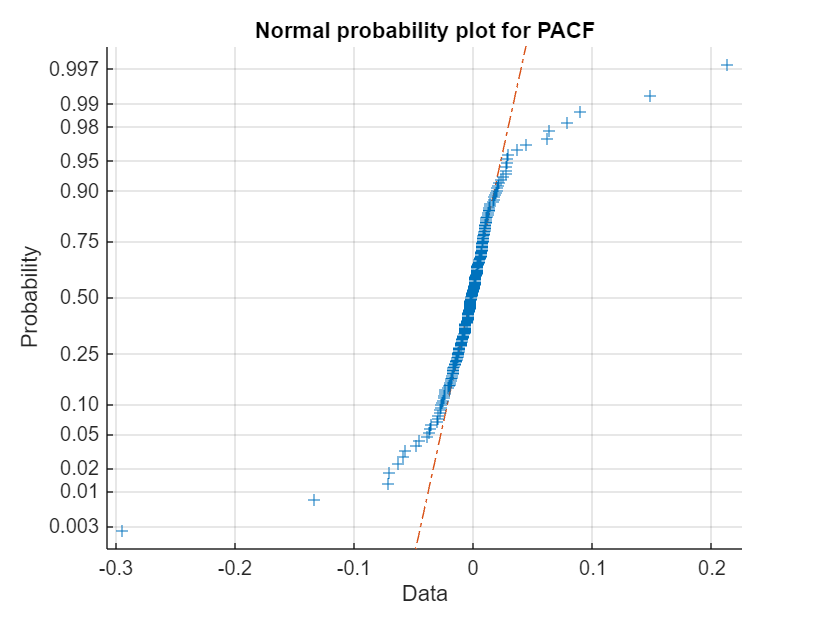

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );

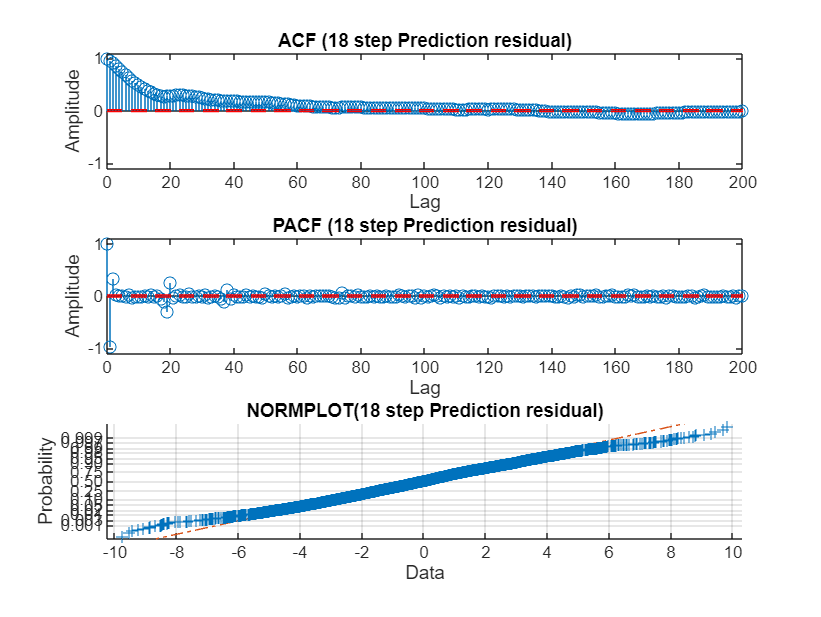

yhat18=predCodeA_grp049([],DataInd,DataTestInd,18);
ehatA_P1 = DataTest-yhat18;
var_predA_1a = var( ehatA_P1 );
[~, pacfEst_a1] = acfs( ehatA_P1, nolags, '18 step Prediction residual');


ynaive=filter([zeros(1,24) 1],[1],DataInd);
ynaive=ynaive(DataTestInd);
ehatnaive = DataTest-ynaive;
var_naive=var( ehatnaive );

varY = var( DataTest );
fprintf('Prediction results for the 3-step prediction:\n')

Prediction results for the 3-step prediction:


fprintf('  The variance of the validations data is   %7.2f\n', varY )

  The variance of the validations data is     37.62


fprintf('  The variance of the proposed predictor is %7.2f. The normalized variance is %5.4f.\n', var_predA_1a, var_predA_1a/varY )

  The variance of the proposed predictor is    5.22. The normalized variance is 0.1389.


fprintf('  The variance of the naive predictor is %7.2f. The normalized variance is %5.4f.\n', var_naive, var_naive/varY )
checkIfWhite( ehatA_P1 );

The residual is NOT deemed to be white according to the Monti-test (as 12962.02 > 31.41).


The D'Agostino-Pearson's K2 test indicates that the PACF is NOT normal distributed.


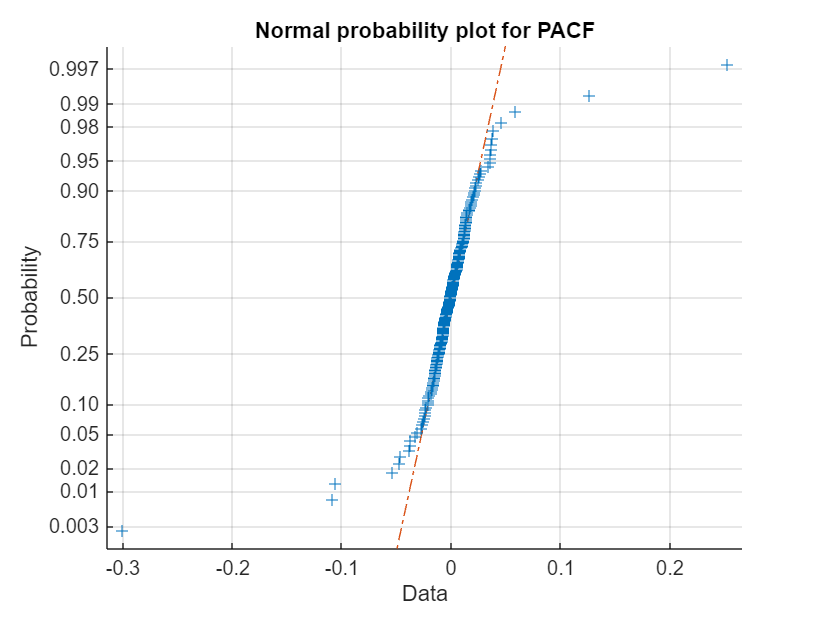

checkIfNormal( pacfEst_a1(k+1:end), 'PACF' );